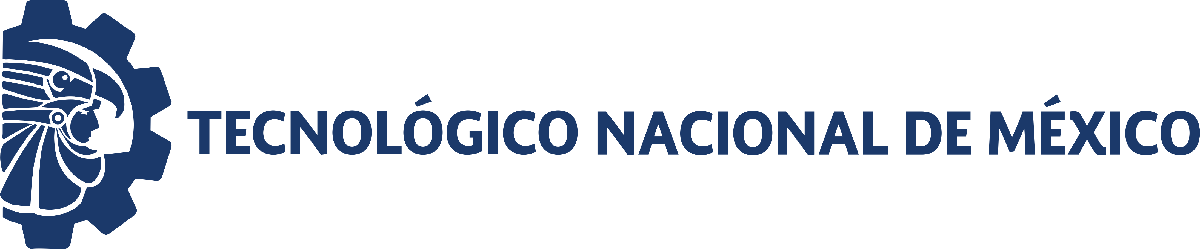                                 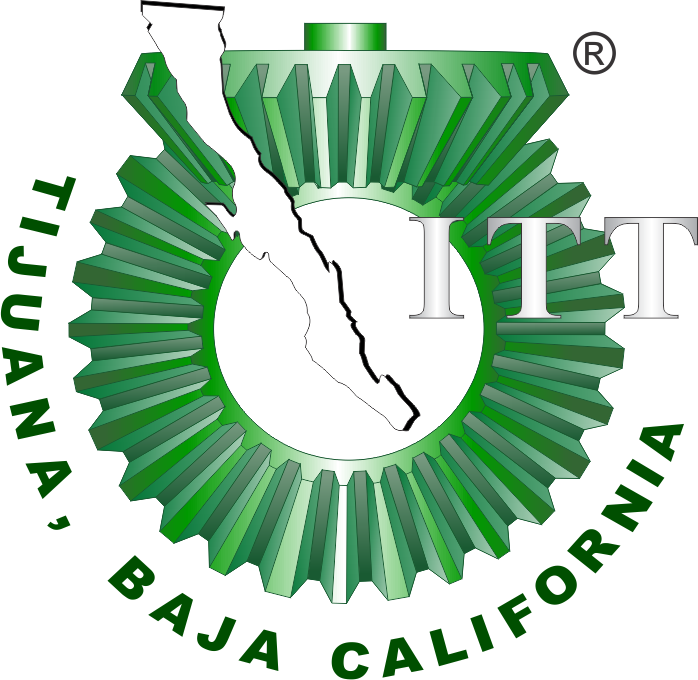

# Proyecto final: Modelado del sistema respiratorio y fisiopatología del asma

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

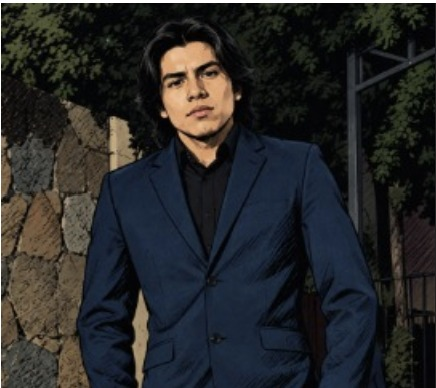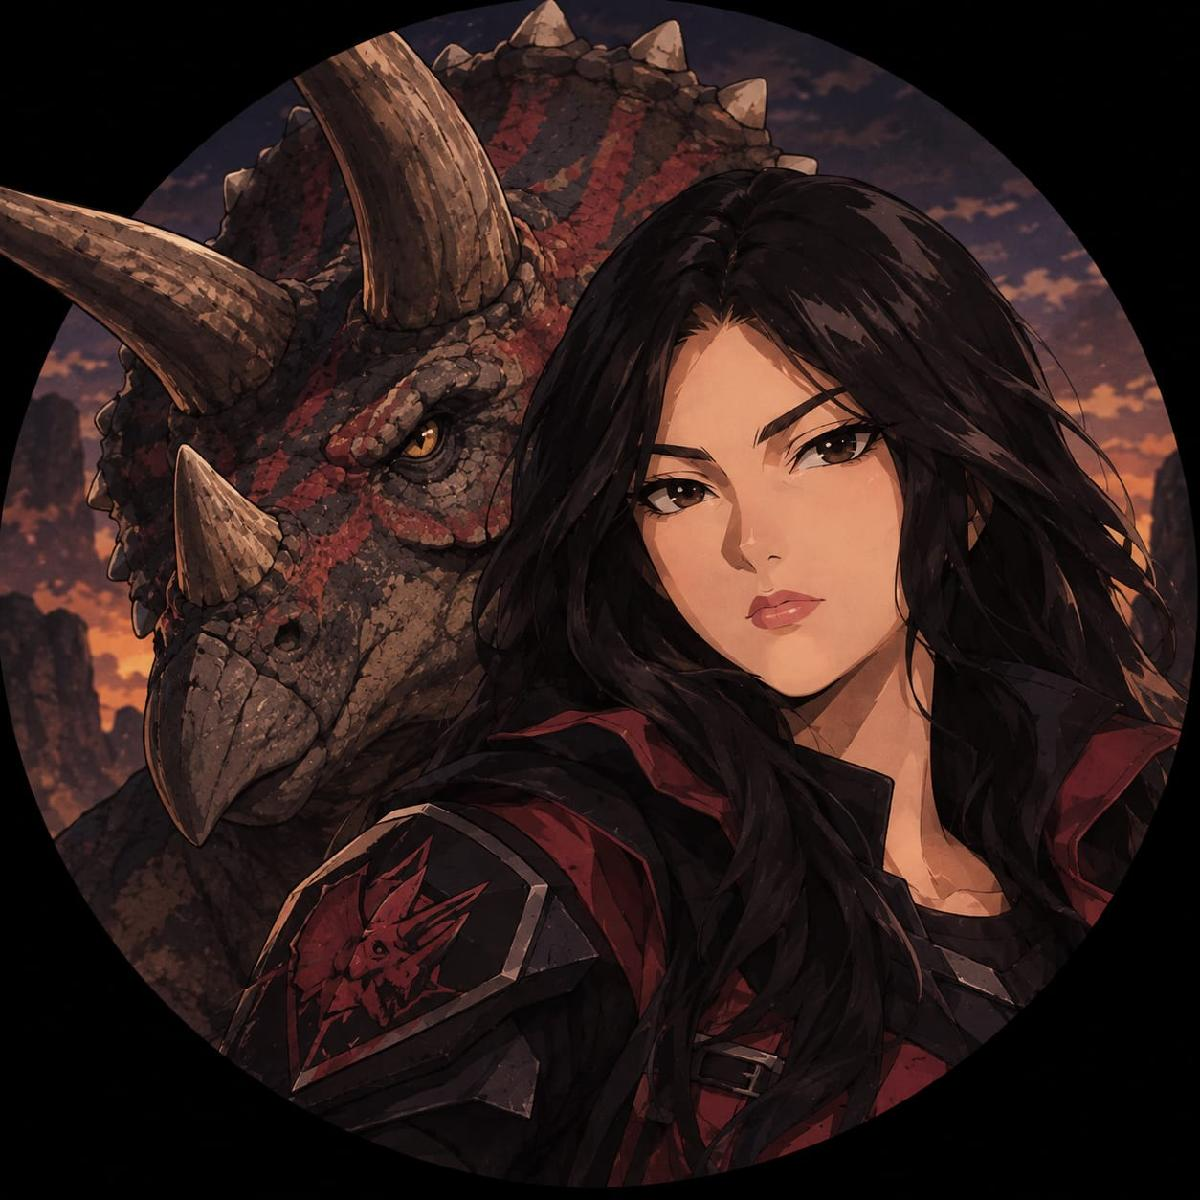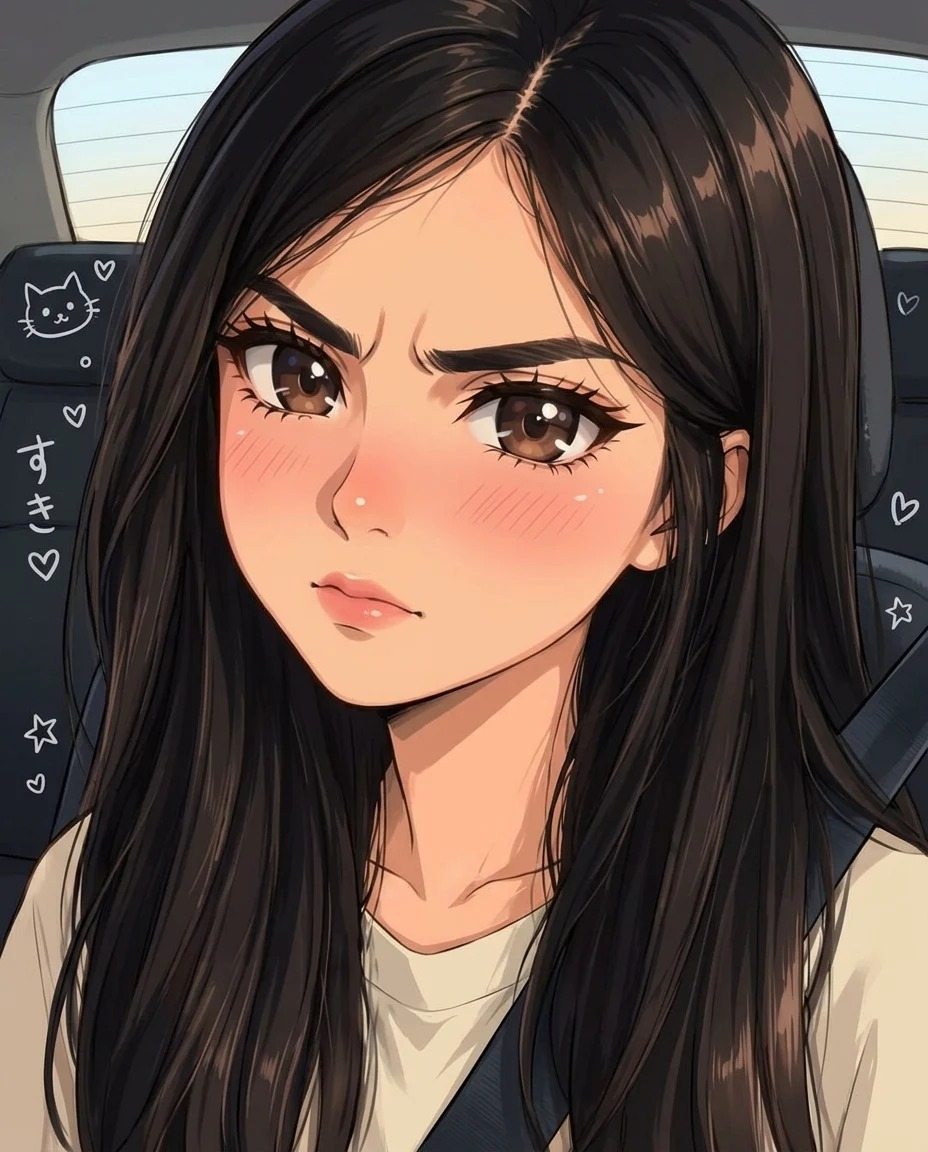

Nombre del alumno: **Cerano Fuentes David Esaú**

                                  **Contreras Jiménez Kenia Yasdit**

                                  **Prado Acosta Briseida**

Número de control: **23210696**

**                                23212188**

**                                23210715**

Correo institucional: **l23210696@tijuana.tecnm.mx**

**                                 l23212188@tijuana.tecnm.mx**

**                                 l23210715@tijuana.tecnm.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Proyecto')                
parameters.StopTime = '15';           
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('Proyecto',parameters); 

## Respuesta del sistema

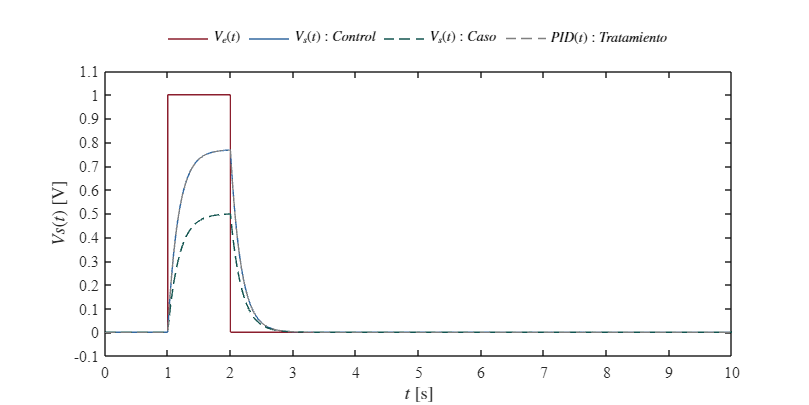

plotsignals(x.t,x.Ve,x.Control,x.Caso,x.PID,'Respuesta')

## Funcion: Respuesta a las señales    

function plotsignals(t,V,C,Cs,PID,name)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,10,5])
set(gca,'fontname','times new roman','fontsize',12)
hold on; grid off; box on;
clr1 = [139, 30, 45] / 255;
clr2 = [51, 104, 160] / 255;
clr3 = [18, 84, 79] / 255;
clr4 = [0.5, 0.5, 0.5];
order = [clr1;clr2;clr3;clr4]; colororder(order)

plot(t,V,'-','LineWidth',0.25,'Color',clr1)  %V(t)
plot(t,C,'-','LineWidth',0.25,'Color',clr2)  %Control
plot(t,Cs,'--','LineWidth',0.25,'Color',clr3)  %Caso
plot(t,PID,'--','LineWidth',1,'Color',clr4)     %PID Tratamiento

L = legend('$V_e(t)$','$V_s(t):Control$','$V_s(t):Caso$','$PID(t):Tratamiento$');
set(L,'interpreter','latex','location','northoutside','orientation','horizontal','box','off')

xlabel('$t$ [s]','interpreter','latex')
ylabel('$Vs(t)$ [V]','interpreter','latex')

xlim([0 10]); xticks(0:1:10)
ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
exportgraphics(gcf,['matlab_', name, '.pdf'],'ContentType','vector')
end
